# Algoritmo Numéricos Por Computadora

# Examen Final

## **Nombre**: Rebeca Baños García

Tu script debe desplegar todas las respuestas en línea (Output Inline). Imprímelo y (además) envíalo a marcelo@itam.mx

## 1. Uso eficiente de un lenguaje de programación matricial 

1.1 Calcula la suma del último renglón de la matriz A (de la manera más "elegante" posible)

 A = [1,2,-1;2,1,-2;-3,1,1;1,2,3]

A =      1     2    -1
     2     1    -2
    -3     1     1
     1     2     3


 suma = sum(A(end,:));
 disp(suma);

     6


1.2 Reemplaza la primera columna de A con ceros. 

A(:,1) =zeros(length(A),1);
disp(A);

     0     2    -1
     0     1    -2
     0     1     1
     0     2     3


## 2. Errores numéricos de las soluciones computacionales

2.1 La serie infinita


$$f\left(n\right)=\sum_{i=1}^n \frac{1}{i^4 }$$


converge a $\frac{\pi^4 }{90}$ conforme $n$ tiende a infinito. Escribe un programa de precisión sencilla para calcular $f\left(n\right)$ para $n=10000$, calculando la suma desde $i=1$ hasta 10000 y después en sentido inverso En cada caso, calcula el error absoluto. 

 real = single(pi^4/90);
 suma = single(0);

for i = 1:10000
    suma = suma + 1/i^4;
end

disp(suma);

    1.0823


errorAbs = real-suma;
disp(errorAbs);

  1.0729e-06



sumaInv = 0;

for j=10000:-1:1
    sumaInv = sumaInv + 1/j^4;
end

disp(sumaInv);

    1.0823


errorAbs1 = real-suma;
disp(errorAbs1);

  1.0729e-06


Explica los resultados.

El error entre ambos métodos es un número elevado a la menos 7, por lo que es un error pequeño y podemos tomar los resultados como exitosos comparandolos con el valor real. 

2.2 Determina el número de términos necesarios para aproximar $\mathrm{cos}\left(0\ldotp 3\pi \right)\;$ a 8 decimales con el uso de la serie de Maclaurin.

$\mathrm{cos}\;x=1-\frac{x^2 }{2!}$+$\frac{x^4 }{4!}$-$\frac{x^6 }{6!}$+$\frac{x^8 }{8!}-\cdots$

cos(0.3*pi)

ans = 0.5878

for i=2:2:10
    res=(-1)*((0.3*pi).^i/factorial(i))
end

res = -0.4441

res = -0.0329

res = -9.7341e-04

res = -1.5440e-05

res = -1.5239e-07

Se necesitan al menos 10 términos para aproximar cos(0.3*pi) a 8 decimales

## 3. Modelado matemático de sistemas físicos

3.1 De acuerdo con el principio de Arquímedes, la fuerza de flotación es igual al peso de fluido desplazado por la porción sumergida de un objeto. Para el tronco de un cono, determina la altura $h_1$ de la porción que queda encima del agua. 

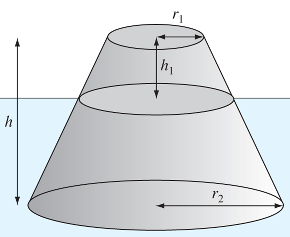

El volumen del tronco está dado por:


$$V=\frac{\pi h}{3}\left({r_1 }^2 +{r_2 }^2 +r_1 r_2 \right)$$


Sea r el radio a la altura de la superficie del agua. Por triángulos semejantes se sabe que:


$$\frac{r-r_1 }{h_1 }=\frac{r_2 -r_1 }{h}$$



$$r=r_1 +\frac{r_2 -r_1 }{h}h_1$$


Usa los siguientes valores para el cálculo;

r1 = 0.5;           % m
r2 = 1;
h = 1;
rhoF = 200;         % densidad del cono kg/m^3
rhoA = 1000;        % densidad del agua

f = @(h1) (((pi*h)/3)*(r1^2+r2^2+r1*r2))*(rhoA-rhoF)-(((pi*h1)/3)*(r1^2+(r1+((r2-r1)/h)*h1)^2+r1*(r1+((r2-r1)/h)*h1)))*rhoA;
int = [0,2*r2];

fplot(f, int);

grid on;

biseccion(f,0.8,1)

 0   0.9000000000000000 -67.8060414399797082 3fc9999999999998 


ans = 0.8758

3.2 Manejas un coche a una velocidad constante de 40 km/h de A a B. Cuando llegas a B regresas inmediatamente a A pero a una velocidad constante de 60 km/h. ¿Cuál es la velocidad promedio del viaje completo?

v1 = 40;
v2 = 60;
B = 100;
A = 20;
t1 = abs(B-A)/v1;   %Sacamos la relaciones del tiempo porque entre menos velocidad, mas tiempo se tarda
t2 = abs(B-A)/v2;
prom = ((v1/t1)+(v2*t2))/2;
disp(prom);

    50


## 4. Solución de sistemas de ecuaciones

Se desea resolver el siguiente sistema de ecuaciones no lineales

 
$$y=x^2 +1$$



$$y=2\;\mathrm{cos}\;x$$


Grafica las ecuaciones ($\left.x>0\right)$ para obtener aproximaciones iniciales para $x$ y $y$:

y = @(x) (x^2)+1;
y1 = @(x) 2*cos(x);

int = [-10,10];

fplot(y,int);

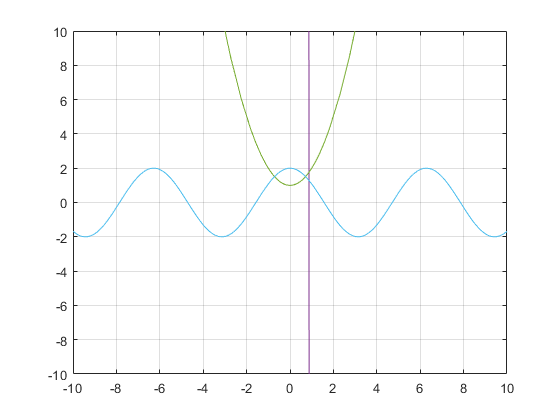

hold on;
ylim([-10 10])

fplot(y1,int);
ylim([-10 10])

Encuentra la solución:

f = @(x) [x(1)^2 - 1 ;
          2*cos(x(1))];

J = @(x) [ 2*x(1);
           2*sin(x(1))];


%Sacar jacobiano
syms xs1;
xs = xs1;
fs = [xs1^2 - 1 ;
      2*cos(xs1) ];
      
Js = jacobian(fs,xs)

$$Js = \left(\begin{array}{c} 2\,{\mathrm{xs}}_{1}\\ -2\,\sin\left({\mathrm{xs}}_{1}\right) \end{array}\right)$$

x = [-2; 2];
[res,iter] = newtonRaphsonVar(f,J,x)

res =     1.1642
    5.1642


iter = 67

## 5. Solución de ecuaciones diferenciales

Se lanza un proyectil hacia arriba desde la superficie de la Tierra con una velocidad inicial de 1500 m/s. Se acepta que la única fuerza que actúa sobre el objeto es la fuerza debida a la gravedad hacia abajo. En estas condiciones, se usa un balance de fuerzas para obtener:


$$\frac{\textrm{d}}{\textrm{d}t}v=-g\frac{R^2 }{{\left(R+x\right)}^2 }$$


donde $v$ es la velocidad hacia arriba (m/s) y $x$ es la altitud (m) medida hacia arriba a partir de la superficie terrestre. 

Grafica la altura $x$ del proyectil en los primeros 250s de vuelo.

R = 6.37e6;
g = 9.81;

f = @(t,y) [y(2);-g*((R^2)/(R+y(1)^2))];
          
y0=[0;1500];

%Método de Rk4
[t,y] = ivps(f,0,250,y0,1,4)

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


y = 	1.0e+09 *

         0   -0.0200   -0.0495   -0.0791   -0.1086   -0.1382   -0.1677   -0.1973   -0.2269   -0.2564   -0.2860   -0.3155   -0.3451   -0.3746   -0.4042   -0.4337   -0.4633   -0.4928   -0.5224   -0.5519   -0.5815   -0.6110   -0.6406   -0.6702   -0.6997   -0.7293   -0.7588   -0.7884   -0.8179   -0.8475   -0.8770   -0.9066   -0.9361   -0.9657   -0.9952   -1.0248   -1.0543   -1.0839   -1.1135   -1.1430   -1.1726   -1.2021   -1.2317   -1.2612   -1.2908   -1.3203   -1.3499   -1.3794   -1.4090   -1.4385
    0.0000   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   -0.0296   

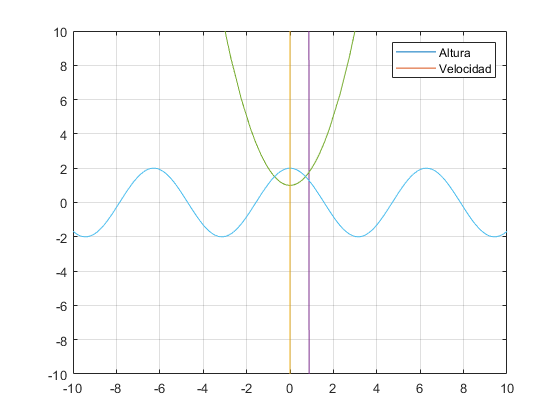

plot(t,y);
grid minor;
legend('Altura','Velocidad')

¿Cuál es, aproximadamente, la máxima altura que alcanza el proyectil?

alturaMax = y(:,end);
disp(alturaMax);

   1.0e+09 *
   -7.3787
   -0.0296
